second order control system

syms Wn E S
C=Wn^2/(S^2+2*E*Wn*S+Wn^2)*1/S

$$C = \frac{{\mathrm{Wn}}^{2}}{S\,\left(S^{2}+2\,\text{E}\,S\,\mathrm{Wn}+{\mathrm{Wn}}^{2}\right)}$$

cb=ilaplace(C)

$$cb = \frac{\delta (t)}{S}-2\,\text{E}\,{\mathrm{e}}^{-\text{E}\,S\,t}\,\left(\cosh\left(S\,t\,\sqrt{{\text{E}}^{2}-1}\right)+\frac{\sinh\left(S\,t\,\sqrt{{\text{E}}^{2}-1}\right)\,\left(\frac{S}{2\,\text{E}}-\text{E}\,S\right)}{S\,\sqrt{{\text{E}}^{2}-1}}\right)$$

syms a b c x;
solve(a*x^2+b*x+c)

$$ans = \left(\begin{array}{c} -\frac{b+\sqrt{b^{2}-4\,a\,c}}{2\,a}\\ -\frac{b-\sqrt{b^{2}-4\,a\,c}}{2\,a} \end{array}\right)$$

syms y(t)
dsolve(diff(y)==sin(t))

$$ans = C_{4}-\cos\left(t\right)$$

dsolve(diff(y)==sin(t),y(0)==2)

$$ans = 3-\cos\left(t\right)$$

syms y(t) a
dsolve('Dy=a*y')

$$ans = C_{6}\,{\mathrm{e}}^{a\,t}$$

syms x
int(sin(x),pi/2,3*pi/2)

$$ans = 0$$

syms x
simplify(sin(x)^2+cos(x)^2)

$$ans = 1$$

clc;
clear all;
syms t 
assume(t>0)
c=1-exp(-t/2)

$$c = 1-{\mathrm{e}}^{-\frac{t}{2}}$$

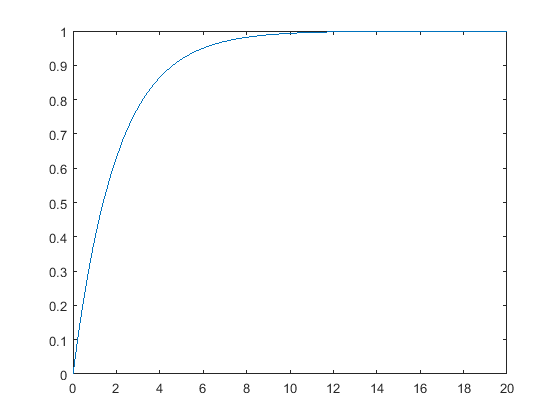

fplot(c,[0 20])

clc;
clear all;
syms x
A=[x+1 x^2;0 3]

$$A = \left(\begin{array}{cc} x+1 & x^{2}\\ 0 & 3 \end{array}\right)$$

B=inv(A)

$$B = \left(\begin{array}{cc} \frac{1}{x+1} & -\frac{x^{2}}{3\,\left(x+1\right)}\\ 0 & \frac{1}{3} \end{array}\right)$$

subs(B,x,1)

$$ans = \left(\begin{array}{cc} \frac{1}{2} & -\frac{1}{6}\\ 0 & \frac{1}{3} \end{array}\right)$$